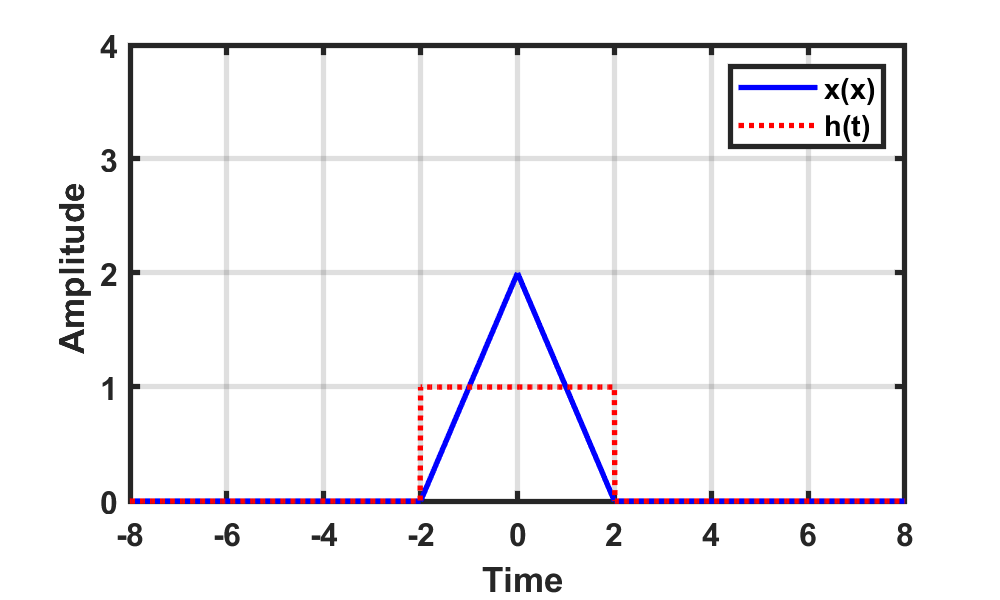

clear; clc ; close all;

syms t   

a = 2;
sig1 = @(t) t .*(t<0 & t>-a)+ -t.*(t>0 & t<a) + a * (t>-a & t<a); % triangle

a = 1; b=2;
sig2 = @(t) a*(abs(t)<=b) + 0; % rectangle

t = -10:0.01:10;

fig1 = figure(1);
set(fig1,'Position', [100 100 500 300]);

plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(t),':r', 'linewidth', 2);
legend('x(x)', 'h(t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-8 8])
set(gca,'fontsize',12,'linewidth',2,'fontweight','bold');

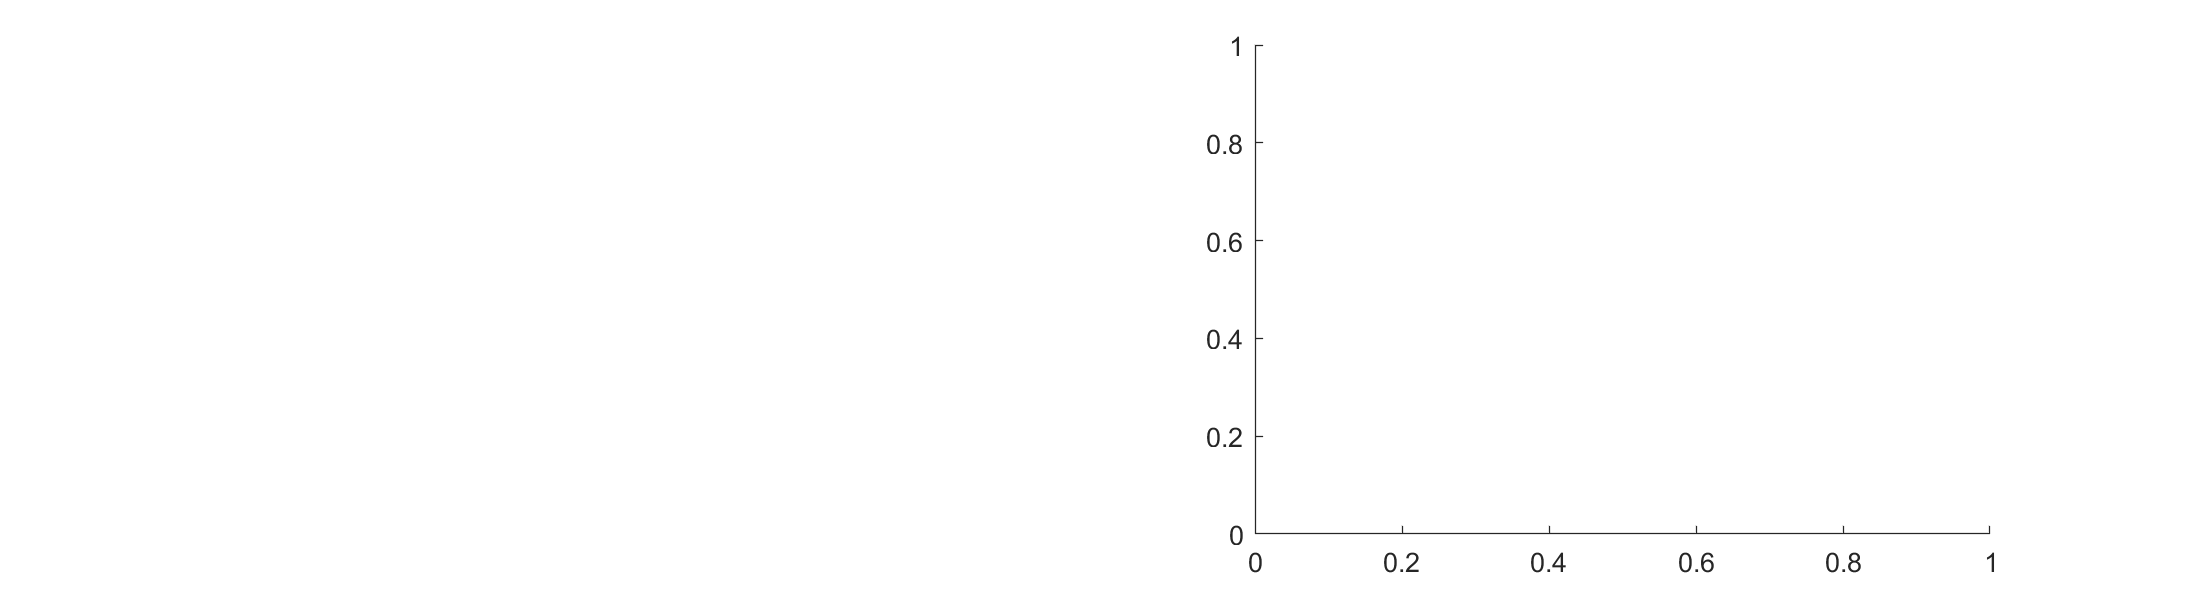



fig2 = figure(2);
set(fig2,'Position', [100 100 1100 300]);

subplot(122); 

plot(t,sig1,'-b', 'linewidth', 2);hold on;

Error using plot
Invalid data argument.

plot(t,sig2(t-4), ':r', 'linewidth', 2); hold off;
legend('x(t)', 'h(t-4)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-8 8])
set(gca,'fontsize',12,'linewidth',2,'fontweight','bold');

subplot(122); plot(t,sig1(t).*sig2(t-2),'-b', 'linewidth', 2);hold on;
legend('h(t) x x(t-2)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-8 8])
set(gca,'fontsize',12,'linewidth',2,'fontweight','bold');

return

sig_conv = conv(sig1(t), sig2(t))*0.01;
plot(t,sig_conv((floor(numel(sig_conv)/4)):floor(numel(sig_conv)/4)*3),'-b', 'linewidth', 2);hold on;
legend('x(t) * h(t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 14])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');


return








fig2 = figure(2);
set(fig2,'Position', [100 100 1100 300]);

sig_conv = conv(sig1(t), sig2(t))*0.01;
plot(t,sig_conv((floor(numel(sig_conv)/4)):floor(numel(sig_conv)/4)*3),'-b', 'linewidth', 2);hold on;
legend('x(t) * h(t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 14])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');


fig3 = figure(3);
set(fig3,'Position', [100 100 1100 600]);

subplot(211); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(-5-t),':r', 'linewidth', 2);hold on;
legend('h(\tau)', 'x(-5-\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf \tau');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(212); plot(t,sig1(t).*sig2(-5-t),'-b', 'linewidth', 2);
legend('h(t) x x(-5-t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 8]);
xlabel('\bf \tau');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');


fig4 = figure(4);
set(fig4,'Position', [100 100 1100 600]);

subplot(211); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(-3-t),':r', 'linewidth', 2);hold on;
legend('h(\tau)', 'x(-3-\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf \tau');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(212); plot(t,sig1(t).*sig2(-3-t),'-b', 'linewidth', 2);
legend('h(\tau) x x(-3-\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 8]);
xlabel('\bf \tau');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');


fig5 = figure(5);
set(fig5,'Position', [100 100 1100 600]);

subplot(211); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(t),':r', 'linewidth', 2);hold on;
legend('h(\tau)', 'x(\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf \tau');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(212); plot(t,sig1(t).*sig2(t),'-b', 'linewidth', 2);
legend('h(\tau) x x(\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 8]);
xlabel('\bf \tau');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');
